# Lecture 1 - 23.05.2023

## Calculation of R - T Relationship of PT1000

clear
clc

## Exercise 1 - Part 1

### Task 1 – Basis Information

a) Open the data sheet (available on Moodle). 

b) Study and focus on the following characteristics: 

- How does the resistance change over temperature from T => 0°C? 

- Check on the coefficients you need.

- Start with Class F 0.6 (C)

### Task 2 – Matlab Program for PT1000 function

Write a Matlab Script including the following points: 

- Calculate the resistance of RT over the full temperature range. 

- Therefore, insert all necessary variables with values. 

- Plot the result of RT (y-axis) over Temperature (x-axis). 

- Make use of the grid minor function for the plot. Label both axis and add a title. 

- Safe your data to a matrix in the workspace. First column for the temperature and the second for the resistance.

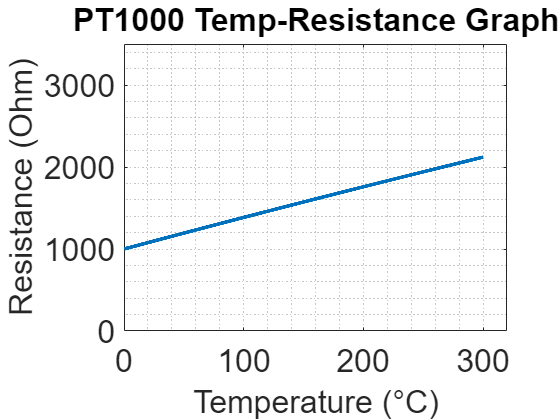

a = 3.9083e-3;
b = -0.5775e-6;
c = -4.183e-12;
R0 = 1e3;
temp_range = 0.1:0.1:300;

r_ptc = R0*(1 + a*temp_range + b*temp_range.^2);
plot(temp_range, r_ptc, 'LineWidth', 3)
grid minor
xlim([0 320]); ylim([0 3500])
title('PT1000 Temp-Resistance Graph')
xlabel('Temperature (°C)'); ylabel('Resistance (Ohm)')

fontsize(24,"points")

result = [temp_range' r_ptc'];

### Task 3 – Wheatstone Bridge

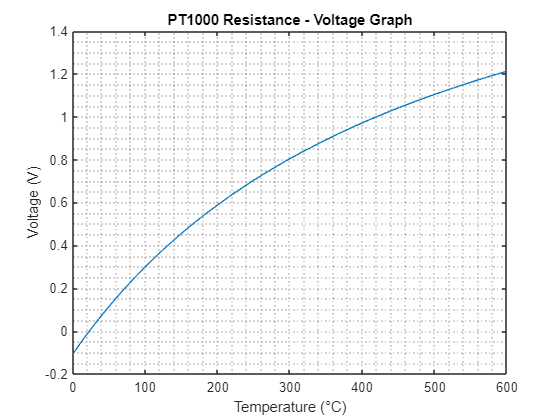

R1 = 1e3;
R4 = 1.088e3; R3 = R4; R2 = R3;
Vs = 5;
V0 = zeros(1, 6000);

for i=1:6000
    V0(i) = Vs*(r_ptc(i)/(r_ptc(i)+R2) - 0.5);
end

plot(temp_range, V0)
grid minor
title('PT1000 Resistance - Voltage Graph')
xlabel('Temperature (°C)'); ylabel('Voltage (V)')

result = [result V0'];

### Task 4 – Calculation of RTself

In real applications we can just measure the output voltage of the bridge. Therefore, we have to rearrange the imbalanced equation from task 3.

- Rearrange 

𝑉0 = 𝑉𝑆 ( (𝑅1 + ∆𝑅1) / (𝑅1 + ∆𝑅1 + 𝑅2 + ∆𝑅2) − (𝑅4 + ∆𝑅4) / (𝑅3 + ∆𝑅3+𝑅4 + ∆𝑅4) )

to find R1+∆R1. 

Include the equation you found in your Matlab Script. Use a new section and the variable RTself. If the result is correct it should show the same values as RT from task 1.

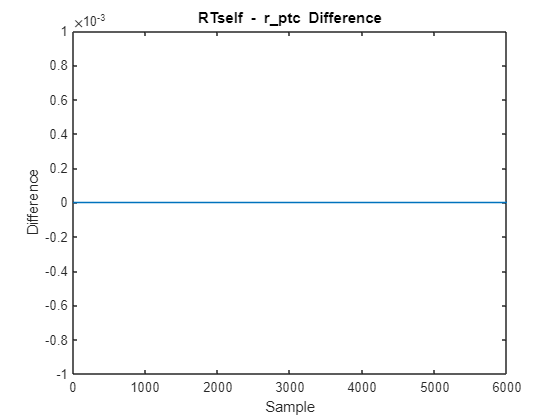

RTself = zeros(1, 6000);

for i = 1:6000
    RTself(i) = (V0(i)/Vs + 0.5) * (r_ptc(i) + R2);
end

plot(RTself - r_ptc)
title('RTself - r\_ptc Difference')
ylabel('Difference'); xlabel('Sample');
ylim([-1e-3 1e-3])

# Lecture 2 - 01.06.2023

### Task 5 - Calculation of the temperature value

To manage to get to a temperature value T, the equation from the data sheet must be rearranged.

- Find the possible solutions for the temperature value T.

- Include solutions in your script in a new section.

- Find the correct solution and plot it over the resistance RTself wit the labeling and title.

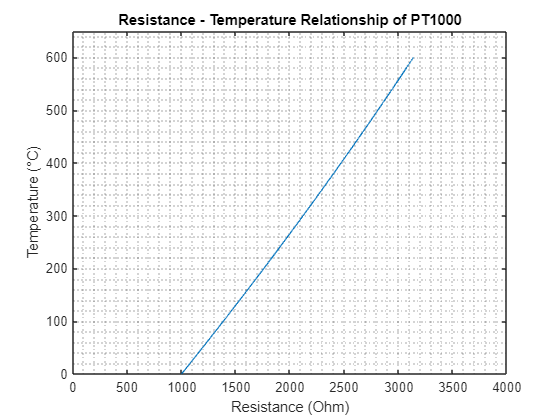

% Calcualte the discriminant of the quadratic equation.
delta = a^2 - 4*b*(1 - r_ptc*1e-3);

% Omit the negative discriminant.
% temp_vs_r_1 = (-a - sqrt(delta)) / (2*b);
temp_vs_r_2 = (-a + sqrt(delta)) / (2*b);

% Plot the result.
plot(r_ptc, temp_vs_r_2)
grid minor
xlim([0 4000]); ylim([0 650]);
xlabel('Resistance (Ohm)'); ylabel('Temperature (°C)');
title('Resistance - Temperature Relationship of PT1000');

### Task 6 - Tolerances

To get a better feeling of the tolerances of the sensor it is possible to calculate and plot it. 

- Add a new section in Matlab and calculate both limits of the sensor. Start with Class F 0.6 (C).

- Plot the result from task 5 together with the calculated tolerances in one plot including labeling and title.

- Check also for the other tolerance classes. 

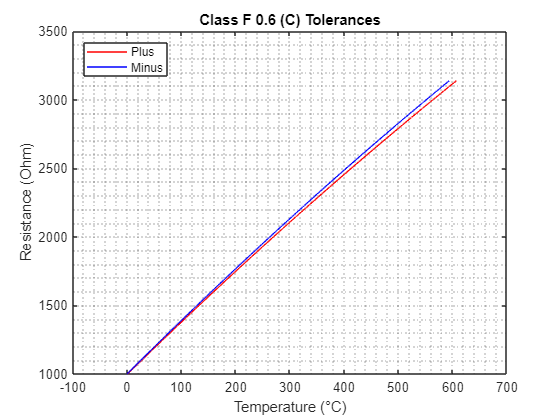

% Class F 0.6 (C)
temp_vs_r_2_plus = temp_vs_r_2 + (0.6 + 0.01*temp_vs_r_2);
temp_vs_r_2_mins = temp_vs_r_2 - (0.6 + 0.01*temp_vs_r_2);

plot(temp_vs_r_2_plus, r_ptc, 'Color','r')
hold on
plot(temp_vs_r_2_mins, r_ptc, 'Color','b')
grid minor
ylabel('Resistance (Ohm)'); xlabel('Temperature (°C)');
title('Class F 0.6 (C) Tolerances');
legend('Plus', 'Minus', 'Location','northwest')

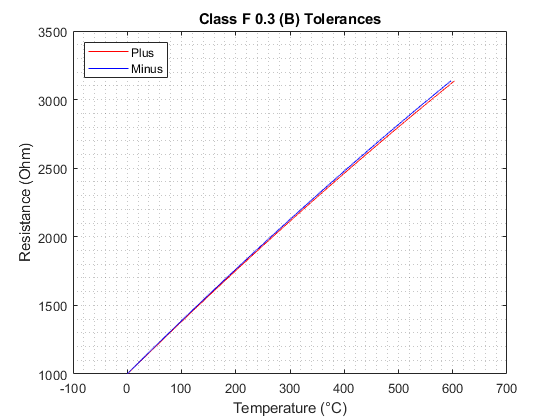


% Class F 0.3 (B)
temp_vs_r_2_plus = temp_vs_r_2 + (0.3 + 0.005*temp_vs_r_2);
temp_vs_r_2_mins = temp_vs_r_2 - (0.3 + 0.005*temp_vs_r_2);

figure
plot(temp_vs_r_2_plus, r_ptc, 'Color','r')
hold on
plot(temp_vs_r_2_mins, r_ptc, 'Color','b')
grid minor
ylabel('Resistance (Ohm)'); xlabel('Temperature (°C)');
title('Class F 0.3 (B) Tolerances');
legend('Plus', 'Minus', 'Location','northwest')

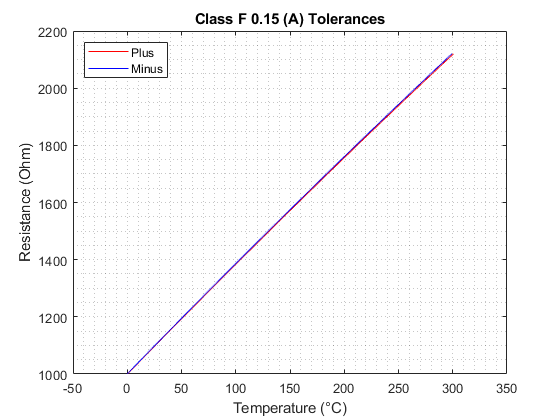

% Class F 0.15 (A)
temp_vs_r_2 = temp_vs_r_2(1:3000);
temp_vs_r_2_plus = temp_vs_r_2 + (0.15 + 0.002*temp_vs_r_2);
temp_vs_r_2_mins = temp_vs_r_2 - (0.15 + 0.002*temp_vs_r_2);

figure
plot(temp_vs_r_2_plus, r_ptc(1:3000), 'Color','r')
hold on
plot(temp_vs_r_2_mins, r_ptc(1:3000), 'Color','b')
grid minor
ylabel('Resistance (Ohm)'); xlabel('Temperature (°C)');
title('Class F 0.15 (A) Tolerances');
legend('Plus', 'Minus', 'Location','northwest')

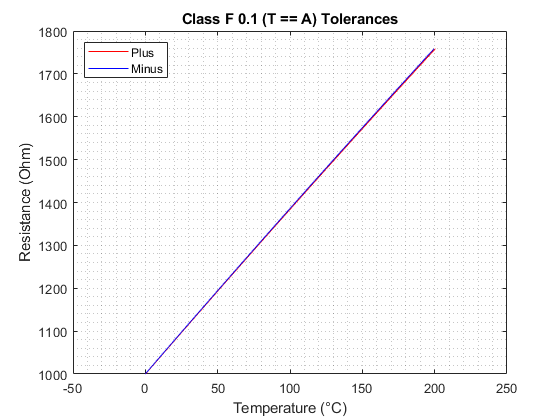

% Class F 0.1 (T == AA)
temp_vs_r_2 = temp_vs_r_2(1:2000);
temp_vs_r_2_plus = temp_vs_r_2 + (0.1 + 0.0017*temp_vs_r_2);
temp_vs_r_2_mins = temp_vs_r_2 - (0.1 + 0.0017*temp_vs_r_2);

figure
plot(temp_vs_r_2_plus, r_ptc(1:2000), 'Color','r')
hold on
plot(temp_vs_r_2_mins, r_ptc(1:2000), 'Color','b')
grid minor
ylabel('Resistance (Ohm)'); xlabel('Temperature (°C)');
title('Class F 0.1 (T == A) Tolerances');
legend('Plus', 'Minus', 'Location','northwest')

### Task 7 - Power Consumption

If all the resistors in the Wheatstone Bridge are 1088 Ohms, then the equivalent resistor of the circuit is

## 
$$\frac{1}{R_{\textrm{eq}} }=\frac{1}{R_1 }+\frac{1}{R_2 }=\frac{1}{2*1088}+\frac{1}{2*1088}\Rightarrow R_{\textrm{eq}} =1088\;\Omega$$


Req = 1088;

Then the current drawn is:

## 
$$\textrm{Vs}=I*R_{\textrm{eq}\;}$$


I = Vs/Req

I = 0.0046

And power consumption is:

## 
$$P=\frac{V^2 }{R_{\textrm{eq}} }$$


P = Vs^2/Req

P = 0.0230

## Exercise 1 - Part 2

### Task 1 – Changing of Parameter 

To get a better feeling for the parameters of the full sensor system try the following changes: 

- Change the supply voltage Vs of the circuit. 

- Change R2, R3 and R4 = 1000Ω 

- Change it back to the original data (Vs = 5V and R2, R3 and R4 = 1088Ω).

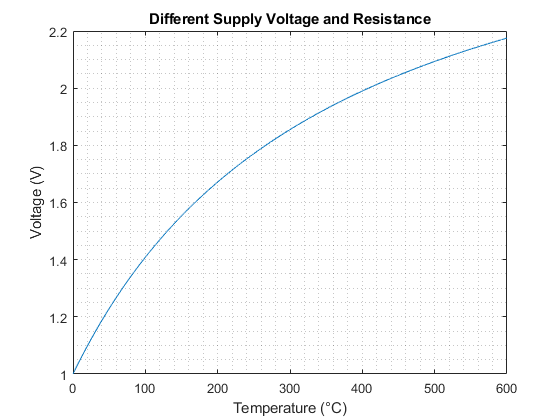

Vs = 6;
R4 = 500; R3 = R4; R2 = R3;
temp_vs_r_2 = (-a + sqrt(delta)) / (2*b);

for i=1:6000
    V0(i) = Vs*(r_ptc(i)/(r_ptc(i)+R2) - 0.5);
end

figure;
plot(temp_range, V0)
grid minor
title('Different Supply Voltage and Resistance')
xlabel('Temperature (°C)'); ylabel('Voltage (V)')

Take-away from this example is that increasing supply voltage and decresing resistor values increase the voltage range of the thermistor.

Decreasing the resistor also does away the negative voltage reading.

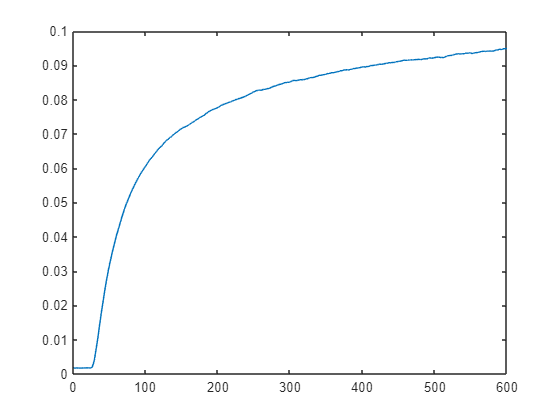

load('V0_TestData.mat');
R4 = 1088; R3 = R4; R2 = R3;
Vs = 5;

plot(DataV0)

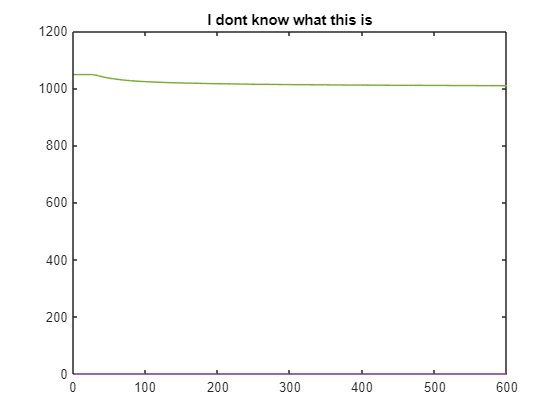

R = 1088 * (2.5 - DataV0) / (2.5 + DataV0);
plot(R)
title('I dont know what this is')

# Lecture 3 - 07.06.2023

### Exercise 3

temp_array = linspace(0, 255, 100)';
res_array = linspace(100, 195.906, 100)';
current = 1e-3;
volt_array = res_array*current;

volt_array_offseted = volt_array - 0.1;
amplification = 50;
volt_array_offset_amplified = volt_array_offseted * amplification;
result_matrix = [temp_array, res_array, volt_array, volt_array_offseted, volt_array_offset_amplified];
result_table = array2table(result_matrix, 'VariableNames',{'Temperature', 'Resistor', 'Voltage', 'Offseted Voltage', 'Offseted Voltage Amplified'});

# Lecture 4 - 15.06.2023

## Heat Flux Sensor

### Exercise 4

S = S0 + (Ts - T0)*Sc

So is the sensitivity at calibration temperature, in μV/(W/m2)  

Sc is the linear correction factor, in (μV/(W/m2))/°C  

To is the calibration temperature, in °C  

Ts is the mean sensor temperature level, in °C

### Task 1: Temperature Corrected Sensitivity

S = S0 + Sc*(Ts - T0);

So is the sensitivity at calibration temperature, in μV/(W/m2)  

Sc is the linear correction factor, in (μV/(W/m2))/°C  

To is the calibration temperature, in °C  

Ts is the mean sensor temperature level, in °C

S0 = 9.41e-6;
Sc = 0.0049e-6;
T0 = 22.5;
Ts = 40;

S = S0 + Sc*(Ts - T0);

disp(['Temperature corrected sensitivity: ', num2str(S), ' uV/W/m/m'])

Temperature corrected sensitivity: 9.4957e-06 uV/W/m/m


### Task 2: Heat Flux Measurement

Heat Flux = Sensor Output Voltage / Temperature Corrected Sensitivity = U / S

output_voltage = 320e-6;
temp_corr_sens = 10.02e-6;
heat_flux = output_voltage / temp_corr_sens;
disp(['Heat Flux: ', num2str(heat_flux), ' W/m/m'])

Heat Flux: 31.9361 W/m/m


### Task 3: Thermal Power Measurement

Thermal power = A * U / S = A * Heat Flux

A is the sensor area, in m2 

U is the sensor output voltage, in μV 

S is the temperature-corrected sensitivity of the sensor,  in μV/(W/m2) 

A = 100e-6; % quadratmeter
thermal_power_1 = A * output_voltage / temp_corr_sens;
thermal_power_2 = A * heat_flux;
disp(['Thermal Power Method 1: ', num2str(thermal_power_1), ' W'])

Thermal Power Method 1: 0.0031936 W


disp(['Thermal Power Method 2: ', num2str(thermal_power_2), ' W'])

Thermal Power Method 2: 0.0031936 W


### Task 4: Units

S0 = 9.41e-6;
Sc = 0.0049e-6;
T0 = 22.5;
Ts = 40;
S = S0 + Sc*(Ts - T0);
disp(['Temperature corrected sensitivity: ', num2str(S), ' V*s^3/kg'])

Temperature corrected sensitivity: 9.4957e-06 V*s^3/kg


output_voltage = 320e-6;
temp_corr_sens = 10.02e-6;
heat_flux = output_voltage / temp_corr_sens;
disp(['Heat Flux: ', num2str(heat_flux), ' kg/s^3'])

Heat Flux: 31.9361 kg/s^3


A = 100e-6; % quadratmeter
thermal_power_1 = A * output_voltage / temp_corr_sens;
thermal_power_2 = A * heat_flux;
disp(['Thermal Power Method 1: ', num2str(thermal_power_1), ' kg*m^2/s^3'])

Thermal Power Method 1: 0.0031936 kg*m^2/s^3


disp(['Thermal Power Method 2: ', num2str(thermal_power_2), ' kg*m^2/s^3'])

Thermal Power Method 2: 0.0031936 kg*m^2/s^3


### Task 5: Transfer Functions

output_voltage = linspace(0, 320, 321)*10e-6;
transfer_function_1 = output_voltage / S;
plot(transfer_function_1, output_voltage);
xlabel('Output Voltage (10^{-6} V)');
ylabel('Heat Flux W/m^2');
title('Transfer Function 1')

transfer_function_2 = A * output_voltage / S;
plot(transfer_function_2, output_voltage);
xlabel('Output Voltage (10^{-6} V)');
ylabel('Thermal Power W');
title('Transfer Function 2')

### Task 6: Measured Data for Heat Flux Calculation

 sensor_output_voltage =  [1.6941266e-04,  1.6591198e-04,  1.7086662e-04,  1.7204656e-04,  1.6488862e-04,  1.7243242e-04,  1.7442322e-04,  1.7728639e-04,  1.7021246e-04,  1.7049766e-04];
 heat_flux_passing_through_sensor = sensor_output_voltage / S;
 disp(['Voltage - Heat Flux (W/m^2)'])

Voltage - Heat Flux (W/m^2)


 disp(num2str([sensor_output_voltage' heat_flux_passing_through_sensor']))

0.000169413      17.8409
0.000165912      17.4722
0.000170867       17.994
0.000172047      18.1183
0.000164889      17.3645
0.000172432      18.1589
0.000174423      18.3686
0.000177286      18.6701
0.000170212      17.9251
0.000170498      17.9552


# Lecture 5 - 21.06.2023

## Surface Acoustic Wave Device

**FH. Prof. DI Dr.-habil. Mr. Pascal Nicolay from CISMAT**

SAW devices are completely passive components. There are no electronics nor energy source inside. SAW devices utilize piezoelectricity.

Some piezoelectric materials:

- LiNbO_3 

- LiTaO_3

- PZT

Not all crystals are piezoelectric; some of them are. These crystals listed above are fully anisotropic. They might not be piezoelectric in all directions; however, there are techniques for maximizing piezoelectricity in all directions.

### Filtering with a SAW filter:

- Main use for saw devices is filtering. In your mobile phones there are at least 10 saw devices.  

- This is a decades old technology and it allows today's mobile phones. 

### Sensing with a SAW device:

- SAW devices can be used to sense mass, strain or temperature. 

- It is possible to also sense wirelessly with SAW devices. It is based on the fact that SAW is a passive piezoelectric device. It can also be used as RFID tags. With cleverly placed reflectors (on the device). it is possible to identify it. 

### Applications:

- Keyword: extreme conditions! High temperature, high impact, high speed, high acceleration... 

- It can be used as implantable strain sensor. What CISMAT is interested in is implanting this sensor into concrete.

You have to sense sense something in extreme conditions and have an RFID tag, remember this device.

**Notes:**

- Used tools for measurement; Sensideon. Coonected via ethernet. Device measures at 1 Hz frequency. The sensitivity is 0.1 centigrad celcius. For real application measurement every minute is fine. Antenna to receive signals utilizes SMA connector with 50 Ohm impedance. 

- The signal fluctuated (SNR dropped) when the sensor was placed within a concrete block. This is due to the change in dielectric constant on the sensor's environment. The naked sensor had a more stable reading. Nonetheless, measurement from the concrete block was useful. 

# Lecture 6 - 29.06.2023

## Liveplot

## Tasks:

- Generate a sine wave starting from 0 to 2*π. Choose a suitable step size. 

- Calculate the length (points) of the sine wave.

- Open a figure

- Make use of a for-loop 

- Make use of the drawnow command 

- Set the limits of the x- and y-axis

- Add title, xlabel, ylabel, grid minor

- Indicate the max value with a black vertical line. Add a “star” (*) where the max value is located.

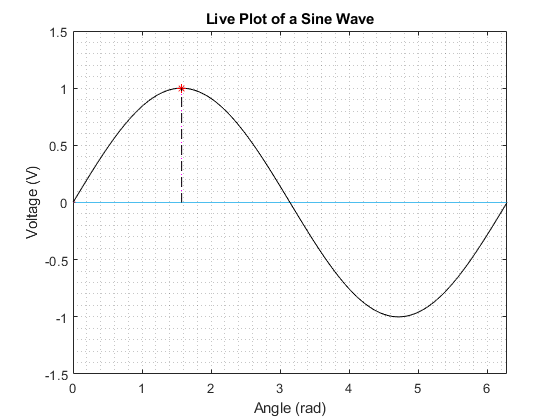

steps = linspace(0,2*pi,1000);
sine_wave = sin(steps);

title('Live Plot of a Sine Wave')
xlabel('Angle (rad)')
ylabel('Voltage (V)')
axis([0 2*pi -1.5 1.5])
method = animatedline;
grid minor

for step = 1:length(steps)
    signal = sin(steps(step));
    addpoints(method, steps(step), signal);
    drawnow
end

hold on

[max_sine_wave, index] = max(sine_wave);
pos_max = steps(index);

plot(pos_max, max_sine_wave, 'r*')
plot([pos_max pos_max], [0 max_sine_wave], '--k')